# Results figures for: The effect of the number motor units and their maximum firing rate in a musculoskeletal model of human reaching

**Cite:** Murtola, T. & Richards, C. (2025) The effect of the number motor units and their maximum firing rate in a musculoskeletal model of human reaching. *bioRxiv*. [https://doi.org/10.1101/2025.09.18.677036](https://doi.org/10.1101/2025.09.18.677036) 

### 1. Trajectories & homing-in error

#### *Load simulation data*

% generate filenames etc
nmus = [1 20];
rmaxs = [20 50];
files = {};
fields = {};
names = {};
for i_mdl = 1:length(nmus)
    for j = 1:length(rmaxs)
        files{length(files)+1} = ['rate_' num2str(nmus(i_mdl)) 'MU_' num2str(rmaxs(j)) 'Hz_fbr_opt.txt'];
        fields{length(fields)+1} = ['N' num2str(nmus(i_mdl)) '_r' num2str(rmaxs(j))];
        names{length(names)+1} = [num2str(nmus(i_mdl)) ' MU(s), r_{max}=' num2str(rmaxs(j)) 'Hz'];
    end
end
nmdls = length(fields);     % number of models


% initialise a structure and read simulation data into it
S = struct;
folder = '..\data';
for i_mdl = 1:nmdls
    S.(fields{i_mdl}) = extract_time_simulation_data(fullfile(folder,files{i_mdl}));
end

dt = diff(S.(fields{1})(1).time(1:2));  % simulation timestep
ntarg = length(S.(fields{1}));          % number of targets


#### *Plot trajectories*

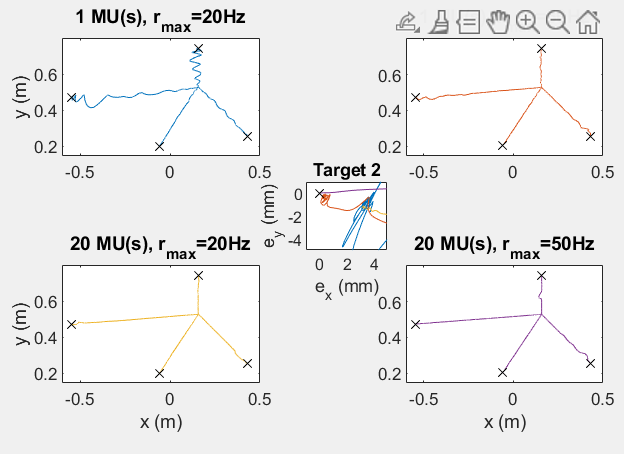

figure
set(gcf,'Units','centimeters')
set(gcf,'Position',[5 5 11 8])
set(gcf,'Visible','on')

%plot_mdl = 1:4;
cmap = colororder();

for j = 1:4
    ax(j) = subplot(2,2,j);
    %mdl_ind = plot_mdl(j);
    for i_mdl = 1:ntarg
        %set(gca,'ColorOrderIndex',j)
        plot(S.(fields{j})(i_mdl).xpos(:,1),S.(fields{j})(i_mdl).xpos(:,2),'Color',cmap(j,:))
        hold on
        plot(S.(fields{j})(i_mdl).xtarg(1), S.(fields{j})(i_mdl).xtarg(2),'kx')
    end
    title(names{j})
    if j > 2
        xlabel('x (m)')
    end
    if mod(j,2)==1
        ylabel('y (m)')
    end
    axis equal
    xlim([-.6 .5])
    ylim([.15 .8])
end

% zoomed-in panel
ax(5) = axes('Position',[.49 .45 .13 .15]);
for j = 1:4  
    i_mdl = 2;      % target 2
    plot((S.(fields{j})(i_mdl).xpos(:,1)-S.(fields{j})(i_mdl).xtarg(1))*1000,(S.(fields{j})(i_mdl).xpos(:,2)-S.(fields{j})(i_mdl).xtarg(2))*1000)
    hold on
end
plot(0, 0,'kx')
xlim([-1 5])
ylim([-5 1])
%axis equal
xlabel('e_x (mm)')
ylabel('e_y (mm)')
%set(gca,'XTick','')
%set(gca,'YTick','')
title('Target 2')

traj_w = 1.5*.2114;
traj_h = 1.5*.3143;

ax(1).Position = [.1 .55 traj_w traj_h];
ax(2).Position = [.65 .55 traj_w traj_h];
ax(3).Position = [.1 .05 traj_w traj_h];
ax(4).Position = [.65 .05 traj_w traj_h];

#### *Calculate & plot homing-in errors*

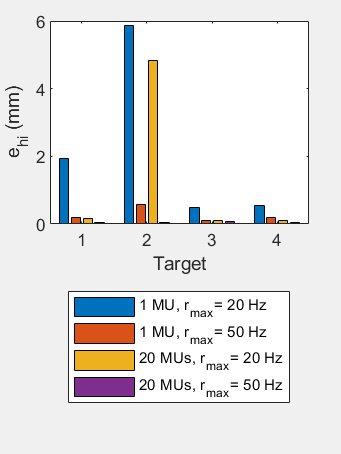

est = average_errors(S);

figure
set(gcf,'Units','centimeters')
set(gcf,'Position',[5 5 6 8])
set(gcf,'Visible','on')

bar(est*1e3)
xlabel('Target')
ylabel('e_{hi} (mm)')
l1 = legend('1 MU, r_{max}= 20 Hz','1 MU, r_{max}= 50 Hz','20 MUs, r_{max}= 20 Hz','20 MUs, r_{max}= 50 Hz');
l1.Location = 'SouthOutside';

#### 2. Homing-in error vs N vs rmax for optimisation targets

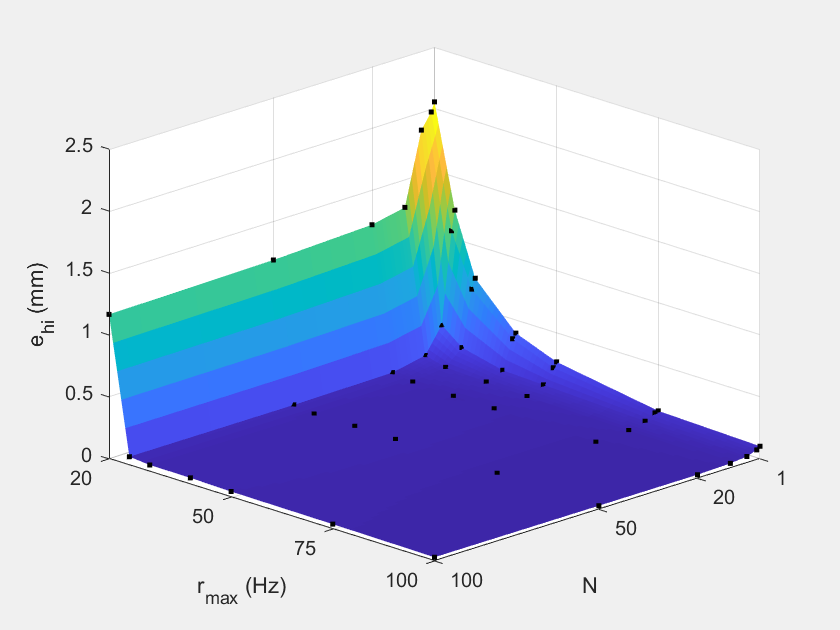

% Homing-in error data in cm

load('..\data\optimal_sols_combined.mat');

nmu = unique(Ttab.N)';
rmax = unique(Ttab.rmax)';
Errs = reshape(Ttab.error,length(nmu),length(rmax));

% generate interpolant
[X, Y] = ndgrid(nmu,rmax);
F = griddedInterpolant(X,Y,Errs');

% interpolate to regular grid
[Xq, Yq] = ndgrid(nmu(1):1:nmu(end),rmax(1):1:rmax(end));
Zq1 = F(Xq,Yq);

figure
set(gcf,'Visible','on')
surf(Xq,Yq,Zq1*10,'EdgeColor','none')
xlabel('N'); ylabel('r_{max} (Hz)'); zlabel('e_{hi} (mm)')
hold on
view(135,25)
hold on
plot3(X,Y,10*Errs','k.','MarkerSize',7)
ylim([20 100])
set(gca,'YTick',[20 50 75 100])
xlim([1 100])
set(gca,'XTick',[1 20 50 100])

#### 3. Homing-in errors across workspace


% load workspace error data (ws_errors) and corresponding target locations (targets),
% numbers of MUs (number_MUs) and rmax values (rmaxs)
load('..\data\ws_errors_all.mat')


inWS = is_in_workspace(targets);     % logical array indicating whether targets are within workspace

% collate data for all models and calculate standard deviation per target
tempE = reshape(ws_errors,length(inWS),[]);
stdE = squeeze(std(tempE,0,2,'omitnan'));


% plot standard deviation by target in main panel
figure
set(gcf,'Units','centimeters')
set(gcf,'Position',[5 5 18 9])
set(gcf,'Visible','on')

ax_main = axes('Position',[.17 .16 .66 .78]);
add_workspace_boundaries(gcf)
hold on
s1=scatter(targets(inWS,1),targets(inWS,2),26,log10(stdE(inWS)),'Marker','s','MarkerFaceColor','flat')

s1 =   Scatter with properties:

             Marker: 'square'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'flat'
          LineWidth: 0.5000
              XData: [-0.6040 -0.6040 -0.5496 -0.5496 -0.5496 -0.5496 -0.5496 -0.5496 -0.5496 -0.5496 -0.4952 -0.4952 -0.4952 -0.4952 -0.4952 -0.4952 -0.4952 -0.4952 -0.4952 -0.4952 -0.4408 -0.4408 -0.4408 -0.4408 -0.4408 -0.4408 -0.4408 -0.4408 … ]
              YData: [0.2570 0.3114 0.0939 0.1482 0.2026 0.2570 0.3114 0.3657 0.4201 0.4745 0.0395 0.0939 0.1482 0.2026 0.2570 0.3114 0.3657 0.4201 0.4745 0.5289 0.0939 0.1482 0.2026 0.2570 0.3114 0.3657 0.4201 0.4745 0.5289 0.5832 0.0939 0.1482 … ]
           SizeData: 26
              CData: [925×1 double]

  Show 

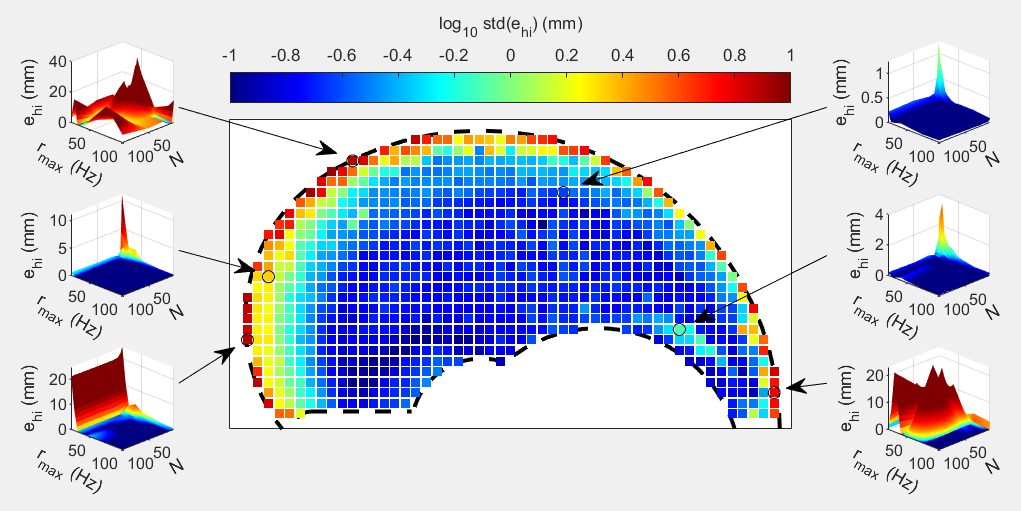

colormap(jet)
view(0,90)
hold on
axis equal
xlim([-.65 .8])
ylim([0 .8])
ax_main.CLim = [-1 1];
c = colorbar(ax_main,'Location','northoutside');
c.Label.String = 'log_{10} std(e_{hi}) (mm)';
ax_main.Box ='on';
ax_main.XTick = [];
ax_main.YTick = [];


% plot secondary panels for selected targets
secAxPos = [0.07 0.12 0.1 0.2;
            0.07 0.42 0.1 0.2;
            0.07 0.72 0.1 0.2;
            0.87 0.12 0.1 0.2;
            0.87 0.42 0.1 0.2;
            0.87 0.72 0.1 0.2];

sel_targs = [637 646 103 392 607 799];  % selected targets

nmu_list = unique(number_MUs);
rmax_list = unique(rmaxs);

[X, Y] = ndgrid(nmu_list,rmax_list);
[Xq, Yq] = ndgrid(nmu_list(1):1:nmu_list(end),rmax_list(1):1:rmax_list(end));

for i_mdl = 1:6
    sax(i_mdl) = axes('Position',secAxPos(i_mdl,:));
    targ_id = sel_targs(i_mdl);
    Err = reshape(tempE(targ_id,:),length(nmu_list),[]);
    F = griddedInterpolant(X,Y,Err);
    surf(Xq,Yq,F(Xq,Yq),log10(F(Xq,Yq)),'EdgeColor','none')
    view(135,25)
    sax(i_mdl).CLim = [-1 1];
    xlim([1 100])
    ylim([20 100])
    xlabel('N','Rotation',30,'Position',[80 150 0]); ylabel('r_{max} (Hz)','Rotation',-30,'Position',[180 140 0]); zlabel('e_{hi} (mm)')    
    plot(ax_main,targets(targ_id,1),targets(targ_id,2),'ko')
end


annotation(gcf,'arrow',[0.175 0.23], [0.25 0.32]);
annotation(gcf,'arrow',[0.175 0.25], [0.51 0.47]);
annotation(gcf,'arrow',[0.175 0.33], [0.79 0.70]);

annotation(gcf,'arrow',[0.81 0.77], [0.25 0.24]);
annotation(gcf,'arrow',[0.81 0.68], [0.50 0.37]);
annotation(gcf,'arrow',[0.81 0.57], [0.79 0.64]);


% calculate medians for targets within workspace for each model
medE = median(tempE(inWS,:));
medE = reshape(medE,7,7);

figure
set(gcf,'Visible','on')
set(gcf,'Position',[5     5     10     4])
bar(medE)
set(gca,'XTickLabel',nmu_list)
ylabel('median e_{hi} (mm)')
xlabel('N')
legend([num2str(rmax_list) repmat(' Hz',7,1)],'Location','EastOutside')


figure
set(gcf,'Visible','on')
set(gcf,'Position',[5     5     10     4])
bar(medE')
set(gca,'XTickLabel',rmax_list)
ylabel('median e_{hi} (mm)')
xlabel('r_{max} (Hz)')
legend([num2str(nmu_list) repmat(' MU',7,1)],'Location','EastOutside')